**PRACTICAL_EXAMPLE_1(PROJECTILE MOTION)**

Suppose we throw a ball from height 20m with velocity 20m/s, equation for height h(t) = 20+40t-6t^2

%h(t) = 20 + 40t - 6t.^2, find when h(t)=0
clc; clear; close all;
s = @(t) 20 + 40.*t - 6.*t.^2; % function
ds = @(t) 40 - 12*t;           %derivative for Newton
%---Bisection Method---
[a, b] = deal(0, 10); %search interval
tic
root_bisect = bisection(s, a, b, 1e-6, 100);
time_bisect = toc;
%---Newton-Raphson method---
tic
root_newton = newton(s, ds, 2, 1e-6, 100);
time_newton = toc;
fprintf('---Root Finding (Projectile)---\n');

---Root Finding (Projectile)---


fprintf('Bisection root: %.6f s (time %.6f s)\n', root_bisect, time_bisect);

Bisection root: 7.133918 s (time 0.017705 s)


fprintf('Newton root:  %.6f s (time %.6f s)\n',root_newton, time_newton);

Newton root:  -0.467251 s (time 0.010991 s)


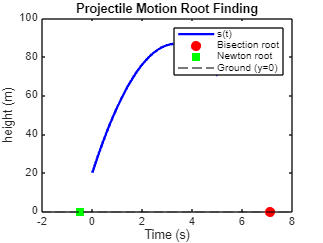

% Plot the function
t_vals = linspace(0, 5, 200);
figure;
plot(t_vals, s(t_vals), 'b-', 'LineWidth',2);
hold on;
yline(0, 'k--');
plot(root_bisect,0,'ro','MarkerSize',8,'MarkerFaceColor','r');
plot(root_newton,0,'gs','MarkerSize',8,'MarkerFaceColor','g');
legend('s(t)','Ground (y=0)','Bisection root','Newton root');
xlabel('Time (s)');
ylabel('height (m)');
title('Projectile Motion Root Finding');

**PRACTICAL_EXAMPLE 2, ODE SOLVING (COOLING PROBLEM)**

Consider Newton's law of cooling; **T(t) = Troom + (To - Troom)e.*-kt**

% dT/dt = -k(T-Tr),T(0)=90, Tr=25, k=0.07
k = 0.07; TO = 90; Tr = 25;
f_ode = @(t, T) -k.*(T - Tr);
tspan = 0:1:60; % time steps (minutes)
%--- Euler Method ---
tic
T_euler = euler(f_ode, tspan, TO);
time_euler = toc;
%--- RK4 Method ---
tic
T_rk4 = rk4(f_ode, tspan, TO);
time_rk4 = toc;
%--- Analytical Solution ---
T_exact = Tr + (TO - Tr).*exp(-k*tspan);
fprintf('\n--- Cooling Problem (ODE) ---\n');


--- Cooling Problem (ODE) ---


fprintf('Euler time: %.6f s\n', time_euler);

Euler time: 0.010338 s


fprintf('RK4 time: %.6f s\n', time_rk4);

RK4 time: 0.017171 s


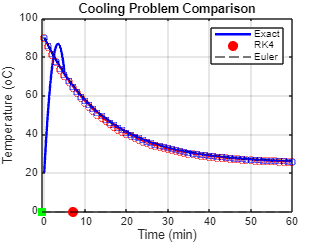

% Plot solutions figure;
plot(tspan, T_exact, 'k-', 'LineWidth',2);
hold on;
plot(tspan, T_euler, 'ro--');
plot(tspan, T_rk4, 'bs-');
legend('Exact','Euler', 'RK4');
xlabel('Time (min)');
ylabel('Temperature (oC)');
title('Cooling Problem Comparison');
grid on;

%--- Helper Functions ----
function root = bisection(s, a, b, tol, N)
    for i=1:N
        c = (a+b)/2;
        if s(c)==0 || (b-a)/2<tol, root=c; return;
        end
        if s(a)*s(c)<0, b=c; else, a=c; end
    end
    root=c;
end
function root = newton(s, ds, x0, tol, N)
    x = x0;
    for i=1:N
        x_new = x - s(x)/ds(x);
        if abs(x_new-x)<tol, root=x_new; return;
        end
        x = x_new;
    end
    root=x;
end
function y = euler(s, tspan, y0)
    y = zeros(size(tspan));
    y(1) = y0;
    h = tspan(2)-tspan(1);
    for i=1:length(tspan)-1
        y(i+1) = y(i) + h*s(tspan(i), y(i));
    end
end
function y =rk4(s, tspan, y0)
    y = zeros(size(tspan));
    y(1) = y0;
    h = tspan(2)-tspan(1);
    for i=1:length(tspan)-1
        k1 = s(tspan(i), y(i));
        k2 = s(tspan(i)+h/2, y(i)+h*k1/2);
        k3 = s(tspan(i)+h/2, y(i)+h*k2/2);
        k4 = s(tspan(i)+h, y(i)+h*k3);
        y(i+1) = y(i) + h/6*(k1+2*k2+2*k3+k4);
    end
end